clear
close all



RC circuit

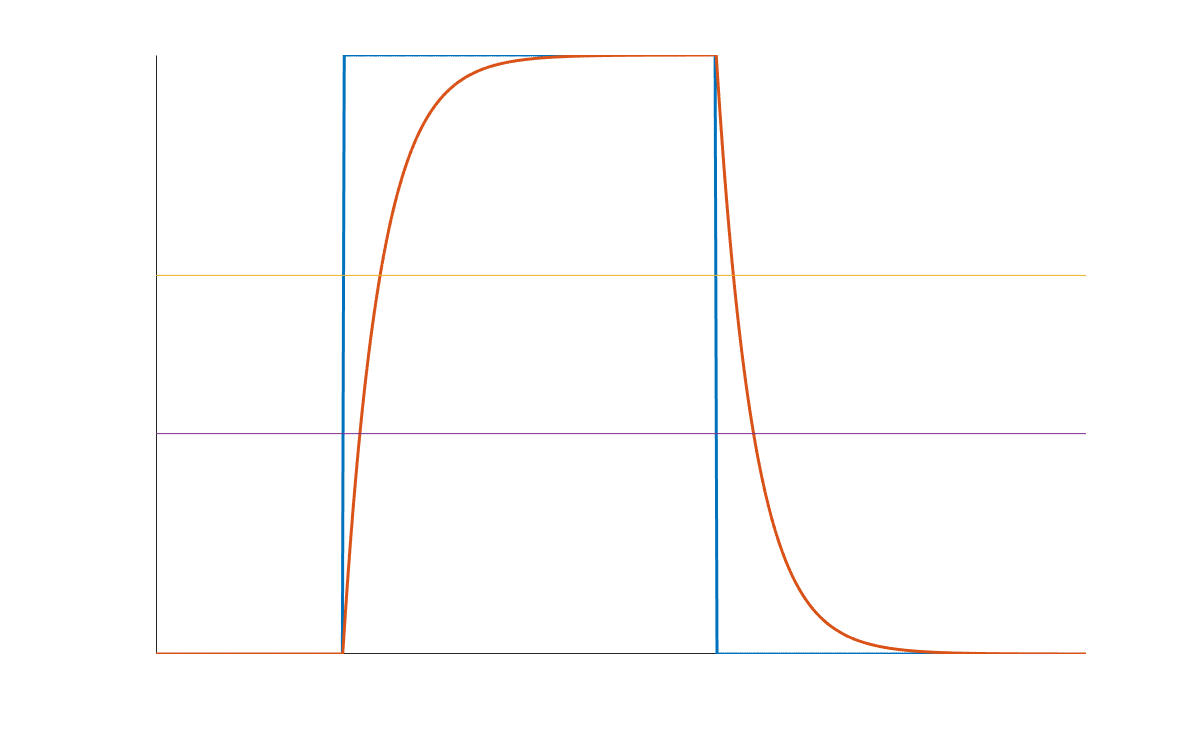

R = 1000;
C = 1e-6;

tmax = 2.49e-2;
t = linspace(0,tmax,500);
f = 0.5e2;
V = @(t) (sin(t*2*pi*f-pi/2)>0);

dVcdt = @(t,Vc) 1/(R*C)*(V(t) - Vc);
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);
[ts, Vcs] = ode45(dVcdt,[t(1),t(end)],0,opts);

figure('outerposition',[1,1,1000,500])

plot(t,V(t),'linewidth',1.5);
hold on
plot(ts,Vcs,'linewidth',1.5);
plot([0,1],[1,1]*0.6321)
plot([0,1],[1,1]*0.3679)
hold off
box off
axis([0,tmax,0,1])
xticks([])
yticks([])

RL Circuit

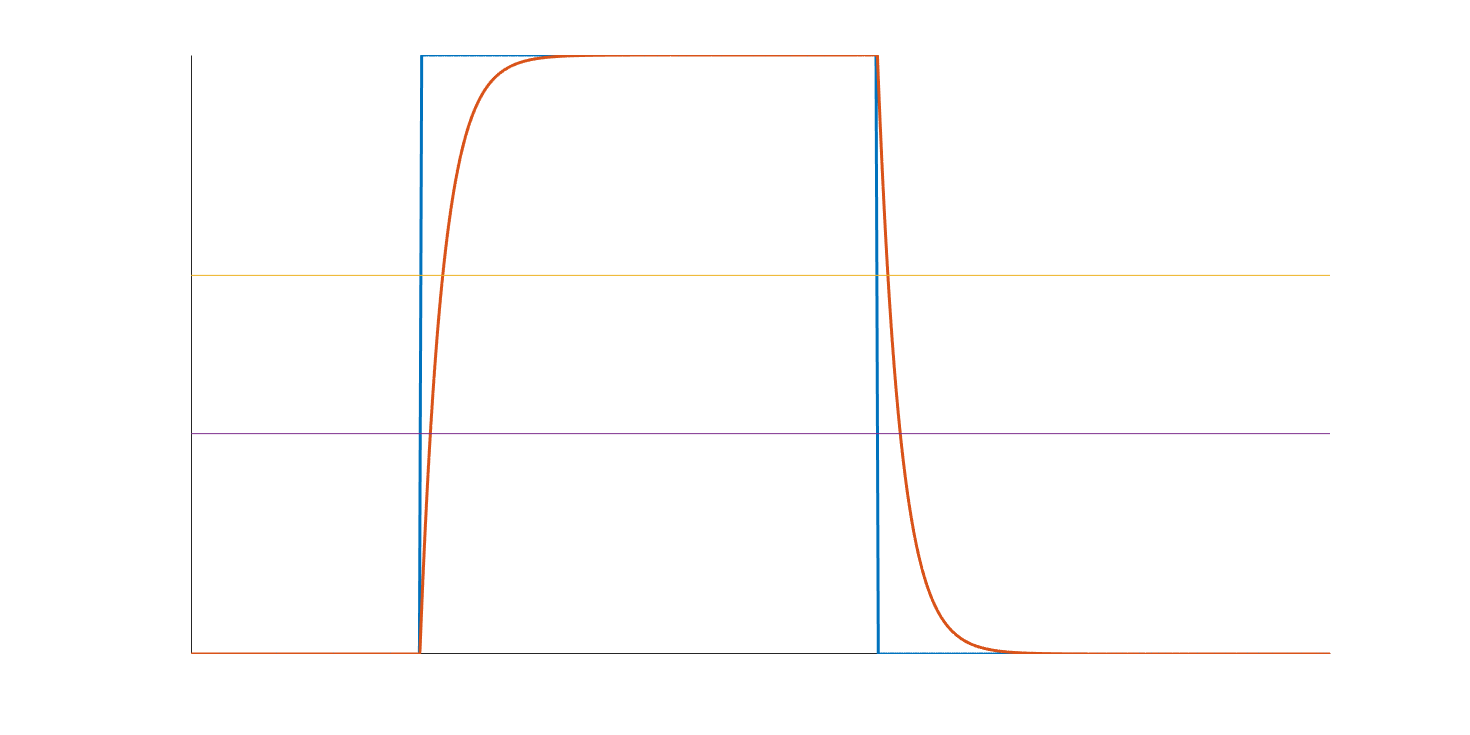

R = 20;
L = 10e-3;

tmax = 2.49e-2;
t = linspace(0,tmax,500);
f = 0.5e2;
V = @(t) (sin(t*2*pi*f-pi/2)>0);

diLdt = @(t,iL) 1/(L)*(V(t) - R*iL);
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);
[ts, iLs] = ode45(diLdt,[t(1),t(end)],0,opts);

figure('outerposition',[1,1,1000,500])

plot(t,V(t)*1/R,'linewidth',1.5);
hold on
plot(ts,iLs,'linewidth',1.5);
plot([0,1],[1,1]*0.6321*1/R)
plot([0,1],[1,1]*0.3679*1/R)
hold off
box off
axis([0,tmax,0,1/R])
xticks([])
yticks([])